clc % clear command window
clear all % clear workspace

1. Set up modeling options, load dataset, and train model. For detailed explanations of these steps, please see the tutorials in the /tutorials/multivariate_regression or /tutorials/multivariate_classification folders. For this example, we just train a model on the full training dataset with hyper-parameter optimization. We will then apply the trained model to an independent test dataset. 

% Add paths to relevant functions
cfg_train.model_dir = '/Shared/boeslab/Users/jcgriffis/ibb_modeling_toolkit/model_code'; % path to toolkit
addpath(genpath(fullfile(cfg_train.model_dir, 'common'))); % add common folder to path

% Specify output directory (Note - output folders for specific analyses will be created in this directory)
out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results';

% Specify data modality and supply brain mask
cfg_train.modality = 'lesion'; % predictor modality - 'lesion' or 'other' 
cfg_train.mask_path = fullfile('/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm/mask/brain_mask.nii'); % path to brain mask

% Specify general modeling options
cfg_train.model_spec = 'logistic_ridge'; % model to fit
cfg_train.fit_explanatory_model = 1; % fit explanatory model to full dataset 
cfg_train.optimize_hyperparams = 1; % use cross-validation to optimize model hyperparameters
cfg_train.cross_validation = 0; % don't use cross-validation to estimate out-of-sample predictive performance
cfg_train.bootstrap = 0; % don't use bootstrap resampling for significance testing of coefficients
cfg_train.permutation = 0; % don't use permutation testing for significance testing of model fit (and/or coefficients)

% Initialize cfg_train file with default settings given general modeling options
cfg_train = get_default_model_cfg(cfg_train); 

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is lesion - setting defaults
MATLAB parallel processing functionality detected; parallel processing enabled


% Specify path to CSV containing study IDs and behavioral scores
train_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/train_csv.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify lesion directory and indicate whether patients are registry patients
lesion_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices
% Note: outputs are stored as fields in cfg_train structure 
cfg_train = get_and_format_lesion_data(train_csv, id_col, beh_col, registry_flag, lesion_dir, cfg_train);

All subjects with behavioral data have lesion files, N=141 patients will be included


% Recode outcome into categorical for his tutorial
cat_Y = zeros(length(cfg_train.Y),1);
cat_Y(cfg_train.Y <= 38) = 1;
cat_Y(cfg_train.Y > 38) = -1;
cfg_train.Y = cat_Y;

% Customize analysis parameters

% Misclassification cost
cfg_train.cost = [0,2.3;1,0]; % Set missclassification cost for positive class to twice that of the negative class

% Lesion-mapping
cfg_train.freq_thresh = 10; % only include voxels that are lesioned in at least 10 patients
cfg_train.dtlvc = 1; % Use direct total lesion volume control (Zhang et al., 2014)

% Variable standardization
cfg_train.standardize = 0; % Standardize (1 - standardize X, 2 - standardize Y, 3 - standardize X & Y)

% Hyper-parameter optimization
cfg_train.hp_opt.cv_type = 'KFold'; % Do K-fold cross-validation for hyper-parameter optimization
cfg_train.hp_opt.folds = 5; % 5-fold cross-validation
cfg_train.hp_opt.repeats = 5; % 5 repeats of 5-fold cross-validation

% Stratification for cross-validation 
cfg_train.strat_var = []; % stratification variable if desired

% Specify output directory
cfg_train.out_dir = fullfile(out_dir, [cfg_train.model_spec '_' beh_col '_independent_pred']);

% fit model with CV hyperparameter optimization and selected significance testing
[model_results] = fit_and_evaluate_model(cfg_train);

Trimming data to retain columns with at least 10 observations greater than or equal to 1
14 subjects have no predictor data after trimming...removing from analysis
Applying direct total lesion volume control...
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:5/5
Optimal lambda = 0.1129, fitting model with optimal lambda
Finished running modeling analysis
Time to to complete:0.12667 minutes


2. Now that we've trained the model, we load in the data for the test set. We store it in a new cfg struct named "cfg_test". We also copy in the brain mask indices from the cfg_train struct to allow for extracting the in-brain voxels from the test set lesion images. Note that this assumes that the lesion images for the training and test datasets are registered to the same template and have the same image and voxel dimensions. The new "cfg_test" struct contains the behavioral data and lesion data for the test dataset.  

% Load test dataset behavior and lesion data

% Specify path to CSV containing study IDs and behavioral scores
test_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/test_csv.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify lesion directory and indicate whether patients are registry patients
lesion_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices
cfg_test = struct(); % Create new cfg_train struct to store data for test set
cfg_test.mask_inds = cfg_train.mask_inds; % Assign same brain mask as training set
cfg_test = get_and_format_lesion_data(test_csv, id_col, beh_col, registry_flag, lesion_dir, cfg_test);

All subjects with behavioral data have lesion files, N=141 patients will be included


% Recode outcome into categorical for his tutorial
cat_Y = zeros(length(cfg_test.Y),1);
cat_Y(cfg_test.Y <= 38) = 1;
cat_Y(cfg_test.Y > 38) = -1;
cfg_test.Y = cat_Y;

3. Next, we provide the model_results struct and the X subfield of cfg_test (this is the lesion matrix for the test set) to the function predict_new(). This produces predicted scores for the test dataset. For classification models, pred_y is a struct that contains both labels and scores. Labels are defined by using the optimal threshold learned baed on the misclassification costs for the training set to threshold the scores. We can plot the AUC and the classification rates. 

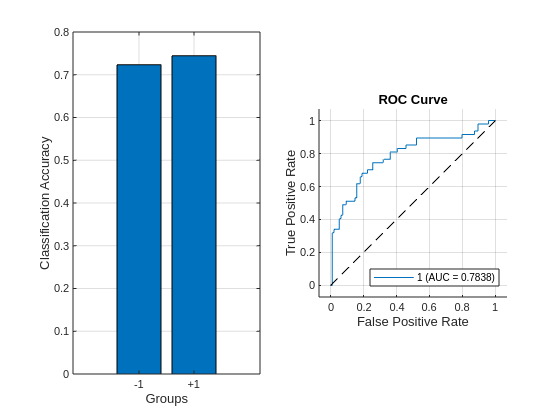

%% Get predictions for test set using trained model
pred_y = predict_new(model_results, cfg_test.X); 

% Compute classification rates
classrate_1 = numel(intersect(find(pred_y.labels == -1), find(cfg_test.Y == -1))) ./ numel(find(cfg_test.Y == -1)); % classification rate for -1 class
classrate_2 = numel(intersect(find(pred_y.labels == 1), find(cfg_test.Y == 1))) ./ numel(find(cfg_test.Y == 1)); % classification rate for +1 class

% Compute ROC Curve
roc_obj = rocmetrics(cfg_test.Y, pred_y.scores, 1);

% Plot results for test set
subplot(1,2,1); 
bar([classrate_1, classrate_2]); grid on;
set(gca, 'XtickLabel', {'-1', '+1'}); xlabel('Groups');
ylabel('Classification Accuracy');
subplot(1,2,2);
plot(roc_obj, "ShowModelOperatingPoint", false); grid on; 